依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

长时间相同光水任务的热图

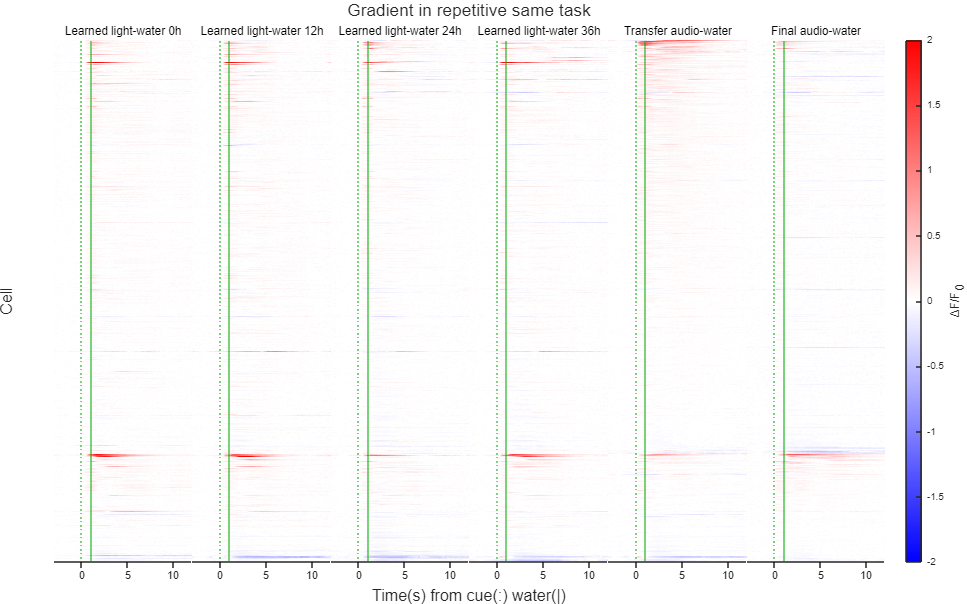

Fig=figure;
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile(Layout,1);
Impl(TransferLearning.Flags.LightAudio|TransferLearning.Flags.PPT,Layout,1);

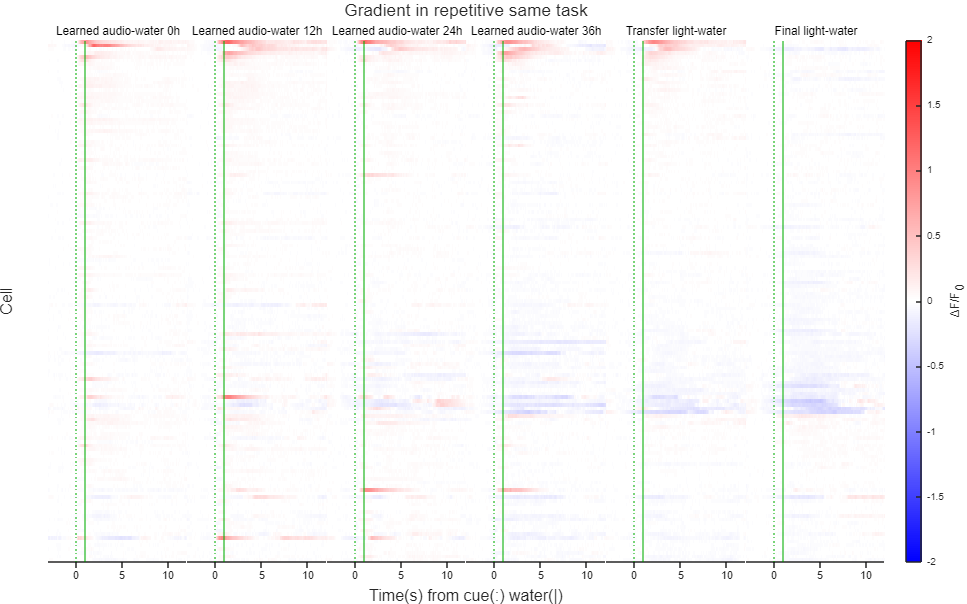

nexttile(Layout,2);
Impl(TransferLearning.Flags.AudioLight|TransferLearning.Flags.PPT,Layout,2);

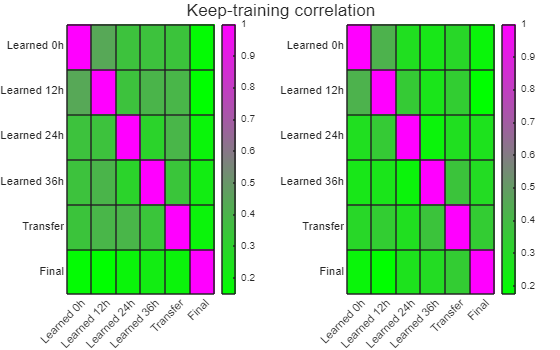

title(Layout,'Keep-training correlation');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow,Fig);
print(Fig,TransferLearning.ProjectPath('持续训练相关性.svg'),'-dsvg');

function Impl(FigureFlag,CorrelationLayout,CorrelationTile)
import TransferLearning.*
switch FigureFlag&Flags.Paradigm
	case Flags.LightAudio
		SheetName='光声持续训练';
		SubTitles=["Learned light-water 0h","Learned light-water 12h","Learned light-water 24h","Learned light-water 36h","Transfer audio-water","Final audio-water"];
	case Flags.AudioLight
		SheetName='声光持续训练';
		SubTitles=["Learned audio-water 0h","Learned audio-water 12h","Learned audio-water 24h","Learned audio-water 36h","Transfer light-water","Final light-water"];
	otherwise
		Exception.Unsupported_paradigm.Throw;
end
GroupNtats=NtatsFromSheetname(SheetName,Flags.Different_cells_stripped);
NTATS=UniExp.HeatmapSort(GroupNtats,["Transfer","Final"],'descend').NTATS{:,:,["Learned_0h","Learned_12h","Learned_24h","Learned_36h","Transfer","Final"]};
Layout=BasicHeatmap(NTATS,SubTitles,GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]),false,CLim=[-2,2]);
MATLAB.Graphics.FigureAspectRatio(8,5,2);
Target=Flags(FigureFlag&Flags.Target);
switch Target
	case Flags.Article
		title(Layout,sprintf('MOp %u cells %u mice',height(GroupNtats),numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,GroupNtats.CellUID))))));
	case Flags.PPT
		title(Layout,'Gradient in repetitive same task');
	otherwise
		Exception.Unsupported_target.Throw;
end
print(ProjectPath(sprintf('%s.%s.svg',SheetName,Target)),'-dsvg');
GroupOrder=["Learned 0h","Learned 12h","Learned 24h","Learned 36h","Transfer","Final"];
persistent CorrelationColormap
if isempty(CorrelationColormap)
	CorrelationColormap=interp2(1:3,[0,255],[0,1,0;1,0,1],1:3,(0:255)');
end
H=heatmap(CorrelationLayout,GroupOrder,GroupOrder,corr(reshape(NTATS,[],6),Type='Spearman'),Colormap=CorrelationColormap);
H.Layout.Tile=CorrelationTile;
end